# tRGS 

In this notebook, we are implementing tensor randomized Gauss Seidel for solving A*X =B.

addpath('tproduct toolbox 2.0 (transform)/')

First, we'll generate a consistent overdetermined tensor linear systems.

l = 20;
p = 10;
n = 30;
m = 40;

%generate tensors
A = randn(m,l,n);
X_true = randn(l,p,n);

%generate consistent measurements
B = tprod(A,X_true);

%generate equivalent matrix system
[matA,matB,matX_true] = matricization(A,B,X_true);

Now, let's test the implementation of tRGS.

%run some iterations of tRGS
num_its = 10000;
errs = tRGS_err(A,B,zeros(l,p,n),num_its,X_true)

errs =    76.7396   75.9474   74.7047   73.8510   71.9688   70.5033   68.3901   68.3793   68.2688   68.0651   66.2368   64.6685   63.2236   63.2236   63.2236   61.3779   61.2003   59.6306   58.0819   58.0471   57.8569   57.8569   56.0556   54.0880   53.9564   53.9624   52.0346   51.6887   51.2711   51.1863   51.1863   50.6385   50.5418   50.5192   50.5187   50.5079   48.0947   47.9221   47.8452   45.3251   45.2692   42.8133   42.6836   42.4529   42.2149   42.2050   41.9418   38.8525   38.7833   38.5383


X_ln = tprod(tpinv(A),B);

%run some iterations of RGS
mat_err = tRGS_err(matA,matB,zeros(n*l,p,1),num_its, matX_true);
matX_ln = tprod(tpinv(matA),matB);


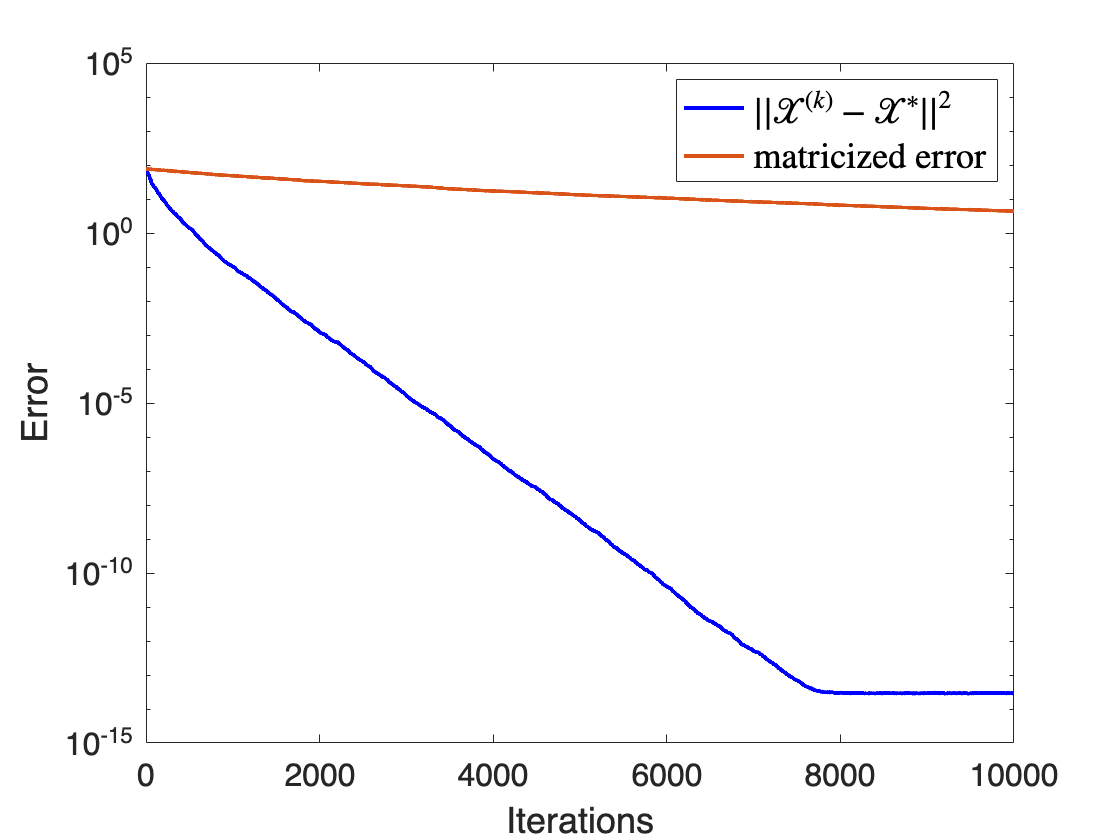

%plot errors vs iterations
figure(1);
semilogy(0:num_its,errs,'b-',0:num_its,mat_err,'LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','matricized error','Interpreter','latex','FontSize',18)
saveas(gca,'fig3.png')
hold off

l = 20;
p = 10;
n = 30;
m = 30;

%generate tensors
A = randn(m,l,n);
X_true = randn(l,p,n);

%generate consistent measurements
B = tprod(A,X_true);

%generate equivalent matrix system
[matA,matB,matX_true] = matricization(A,B,X_true);

Now, let's test the implementation of tRGS.

%run some iterations of tRGS
num_its = 10000;
errs = tRGS_err(A,B,zeros(l,p,n),num_its,X_true)

errs =    76.4350   75.9905   75.4508   74.6087   73.6091   72.7030   71.3846   70.2097   69.0282   67.6569   66.2224   65.9263   65.8591   64.3292   63.1281   63.1281   61.4737   61.2526   59.5437   59.4822   58.6678   56.9097   56.9097   56.6876   54.9449   54.8833   54.6728   54.3442   54.3442   52.0560   51.9874   51.9874   51.3348   51.0648   50.7675   50.7675   48.3631   48.3089   48.2072   48.0481   47.3777   47.3338   46.8559   46.4046   46.3899   46.3338   46.3103   45.9934   45.6289   45.4345


X_ln = tprod(tpinv(A),B);

%run some iterations of RGS
mat_err = tRGS_err(matA,matB,zeros(n*l,p,1),num_its, matX_true);
matX_ln = tprod(tpinv(matA),matB);


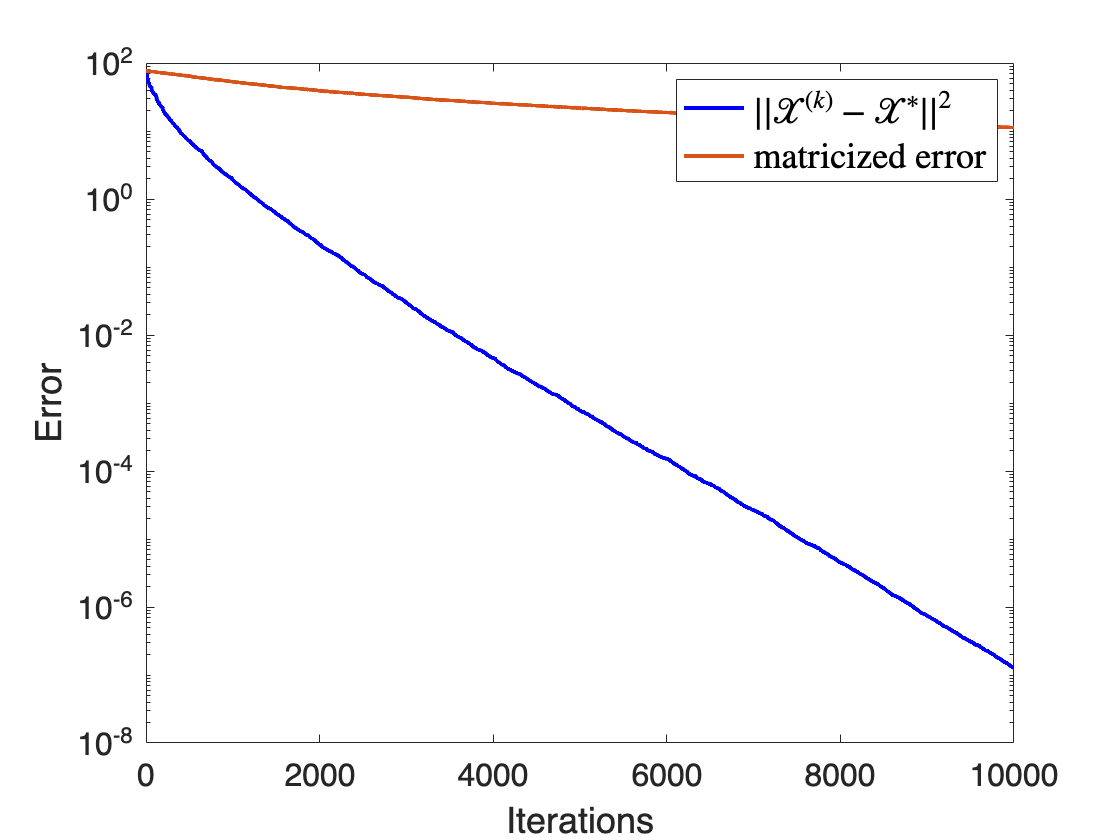

%plot errors vs iterations
figure(2);
semilogy(0:num_its,errs,'b-',0:num_its,mat_err,'LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','matricized error','Interpreter','latex','FontSize',18)
saveas(gca,'fig4.png')
hold off

l = 20;
p = 10;
n = 30;
m = 20;

%generate tensors
A = randn(m,l,n);
X_true = randn(l,p,n);

%generate consistent measurements
B = tprod(A,X_true);

%generate equivalent matrix system
[matA,matB,matX_true] = matricization(A,B,X_true);

Now, let's test the implementation of tRGS.

%run some iterations of tRGS
num_its = 10000;
errs = tRGS_err(A,B,zeros(l,p,n),num_its,X_true)

errs =    77.2100   78.1172   77.4963   76.9190   76.2369   75.3079   74.8143   74.8005   74.2928   73.1457   72.3743   72.3399   71.4160   70.6017   70.5215   70.4869   69.2682   69.3301   69.3571   69.3943   69.3943   69.2619   69.2587   67.8360   67.8687   67.8447   66.7789   65.9314   65.9314   64.9387   64.9941   64.9956   64.9042   64.7160   63.4801   63.4413   63.2176   62.7847   62.6558   62.6131   62.5835   62.5241   62.4921   62.4418   61.0597   61.0123   60.5709   60.5690   59.5528   59.3229


X_ln = tprod(tpinv(A),B);

%run some iterations of RGS
mat_err = tRGS_err(matA,matB,zeros(n*l,p,1),num_its, matX_true);
matX_ln = tprod(tpinv(matA),matB);


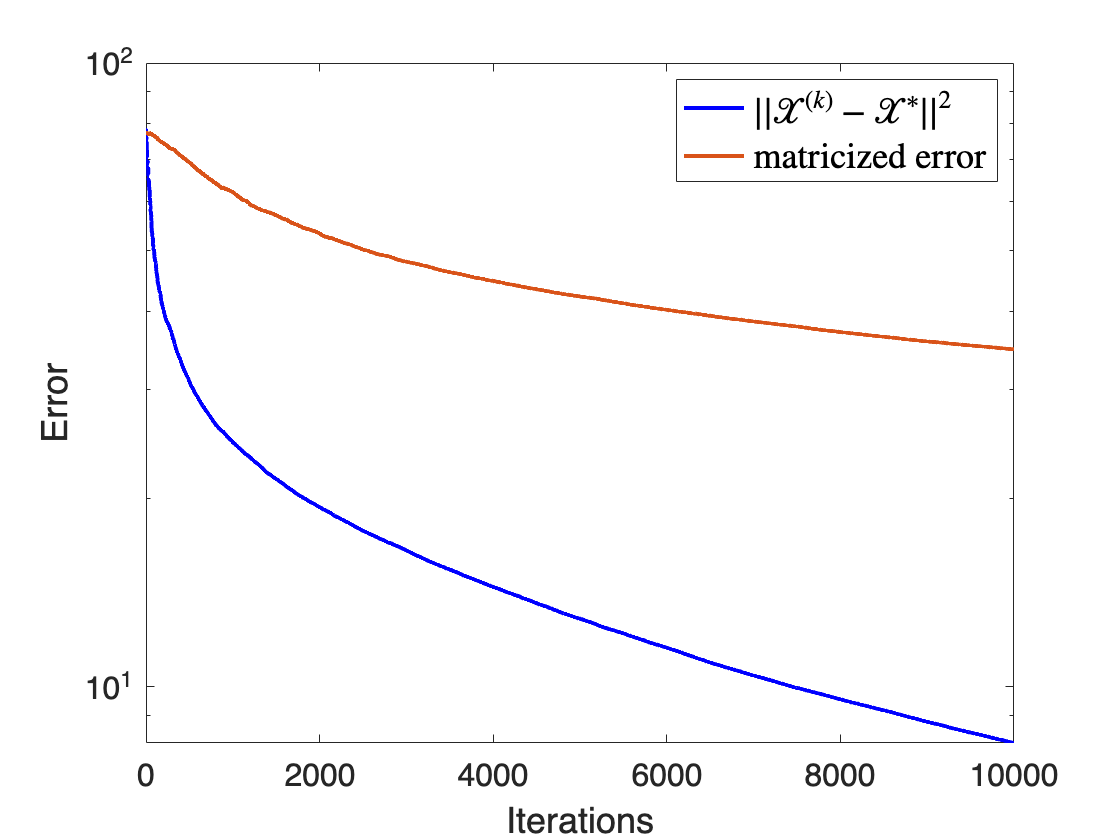

%plot errors vs iterations
figure(3);
semilogy(0:num_its,errs,'b-',0:num_its,mat_err,'LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','matricized error','Interpreter','latex','FontSize',18)
saveas(gca,'fig5.png')
hold off

Now, we shall consider the underdetermined setting:

l = 20;
p = 10;
n = 30;
m = 15;

%generate tensors
A = randn(m,l,n);
X_true = randn(l,p,n);

%generate consistent measurements
B = tprod(A,X_true);

%generate equivalent matrix system
[matA,matB,matX_true] = matricization(A,B,X_true);

Now, let's test the implementation of tRGS.

%run some iterations of tRGS
num_its = 10000;
X_ln = tprod(tpinv(A),B);
errs = tRGS_err(A,B,zeros(l,p,n),num_its,X_ln)

errs =    66.4869   67.2030   66.9268   67.5785   67.0033   66.9273   66.6668   66.4353   66.4592   66.4811   65.6940   65.6783   65.0669   64.0855   64.1531   63.1849   63.1849   62.2567   61.4724   60.7969   59.9170   59.7330   58.8500   58.8278   58.7860   58.3328   58.2488   56.9296   56.8208   56.8208   55.6322   55.3565   55.3441   55.0080   55.0035   55.0024   54.5416   54.3789   54.2901   54.1385   53.9653   53.1689   52.0572   51.9946   51.7287   51.6541   51.5493   51.4953   51.5082   51.4764



res_errs = tRGS_res_err(A,B,zeros(l,p,n),num_its,X_true) 

res_errs = 1.0e+03 *

    1.6194    1.5212    1.4300    1.3646    1.2917    1.2289    1.2243    1.1656    1.0916    1.0330    1.0116    0.9465    0.9008    0.8585    0.8379    0.8174    0.8148    0.7725    0.7258    0.6891    0.6865    0.6785    0.6661    0.6500    0.6250    0.6216    0.6147    0.6142    0.6064    0.5696    0.5654    0.5542    0.5225    0.5209    0.5112    0.5010    0.4993    0.4950    0.4907    0.4676    0.4574    0.4528    0.4466    0.4429    0.4276    0.4234    0.4204    0.4141    0.3891    0.3860


matX_ln = tprod(tpinv(matA),matB);
mat_err = tRGS_err(matA,matB,zeros(n*l,p,1),num_its, matX_ln);
mat_res_err = tRGS_res_err(matA,matB,zeros(n*l,p,1),num_its, matX_true);


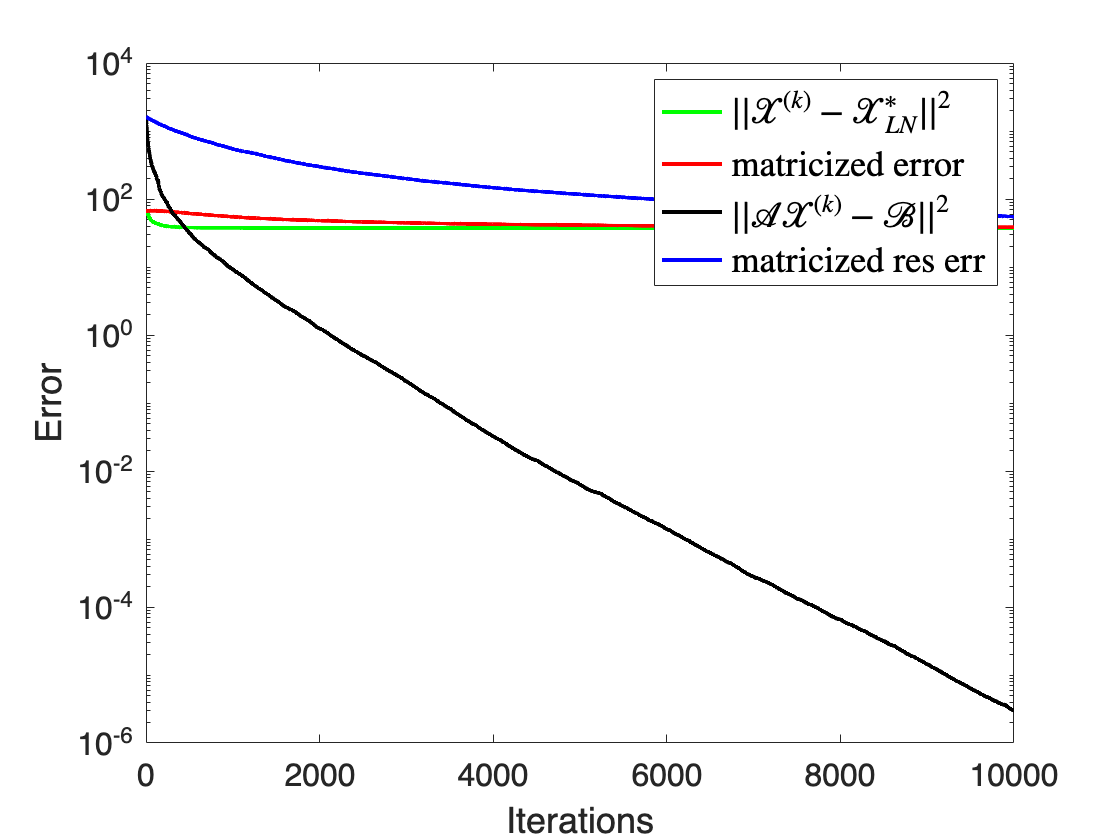

%plot errors vs iterations
figure(4);
semilogy(0:num_its,errs,'g-',0:num_its,mat_err,'r-',0:num_its,res_errs,'k-',0:num_its,mat_res_err,'b-','LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}^*||^2$','matricized error','$||\mathcal{A}\mathcal{X}^{(k)} - \mathcal{B}||^2$','matricized res err','Interpreter','latex','FontSize',18)
saveas(gca,'fig1_1.png')
hold off

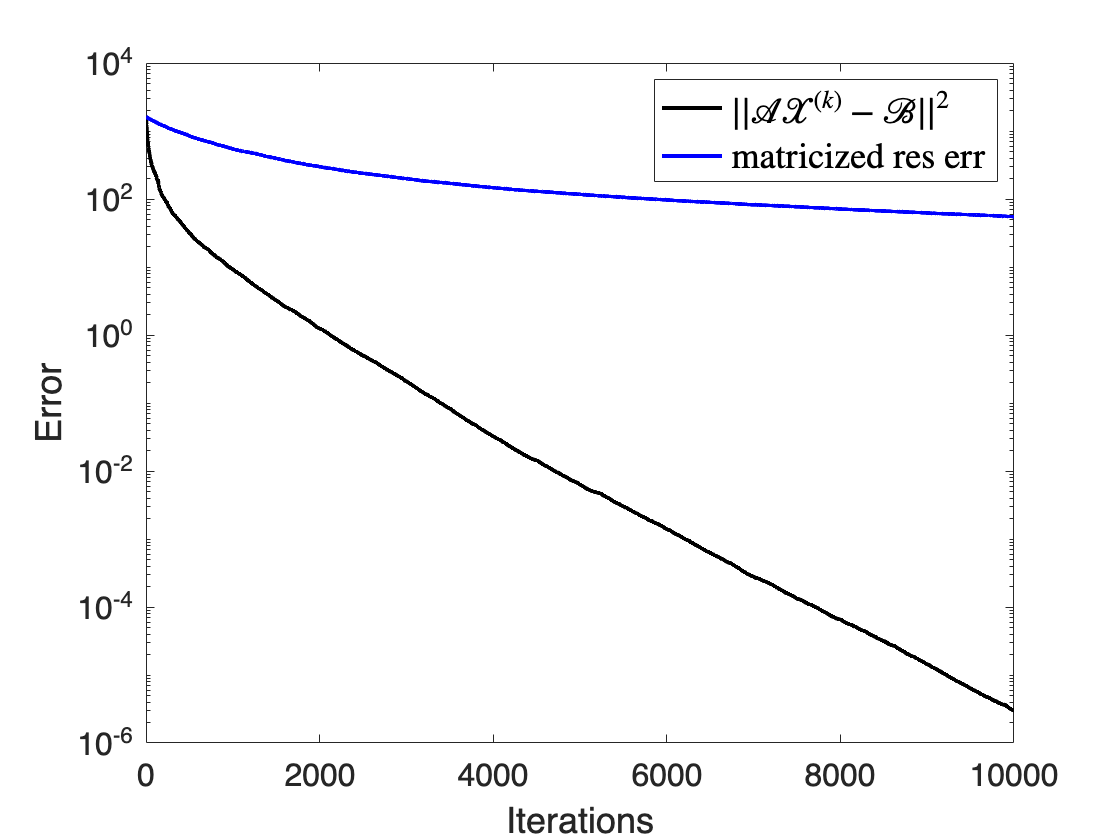

%plot errors vs iterations
figure(5);
semilogy(0:num_its,res_errs,'k-',0:num_its,mat_res_err,'b-','LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{A}\mathcal{X}^{(k)} - \mathcal{B}||^2$','matricized res err','Interpreter','latex','FontSize',18)
saveas(gca,'fig1_2.png')
hold off

l = 20;
p = 10;
n = 30;
m = 10;

%generate tensors
A = randn(m,l,n);
X_true = randn(l,p,n);

%generate consistent measurements
B = tprod(A,X_true);

%generate equivalent matrix system
[matA,matB,matX_true] = matricization(A,B,X_true);

Now, let's test the implementation of tRGS.

%run some iterations of tRGS
num_its = 10000;
X_ln = tprod(tpinv(A),B);
errs = tRGS_err(A,B,zeros(l,p,n),num_its,X_ln)

errs =    56.2155   58.4534   60.1223   59.9886   62.5544   62.8845   62.9578   63.8268   64.3703   64.2701   64.5463   64.7148   64.8478   64.6251   64.2665   64.2665   64.0112   64.0112   63.9461   63.2969   62.8098   62.7469   62.4561   62.6832   62.7443   62.9697   63.0500   62.6006   62.6453   62.7562   62.8780   62.3728   62.3100   62.2737   62.3787   61.8563   61.8837   61.4586   61.4792   61.6226   61.6712   61.3114   61.4289   61.5397   61.5685   61.5536   61.6125   61.5732   61.5888   61.5929



res_errs = tRGS_res_err(A,B,zeros(l,p,n),num_its,X_true) 

res_errs = 1.0e+03 *

    1.4027    1.2764    1.1840    1.1046    1.0141    0.9518    0.8800    0.8237    0.7607    0.7471    0.7456    0.6909    0.6691    0.6565    0.6528    0.6295    0.5943    0.5835    0.5458    0.5458    0.5212    0.4858    0.4519    0.4462    0.4307    0.3989    0.3769    0.3742    0.3654    0.3397    0.3359    0.3279    0.3218    0.3121    0.3013    0.2839    0.2738    0.2522    0.2460    0.2432    0.2429    0.2373    0.2263    0.2225    0.2114    0.2032    0.1975    0.1975    0.1938    0.1864


matX_ln = tprod(tpinv(matA),matB);
mat_err = tRGS_err(matA,matB,zeros(n*l,p,1),num_its, matX_ln);
mat_res_err = tRGS_res_err(matA,matB,zeros(n*l,p,1),num_its, matX_true);


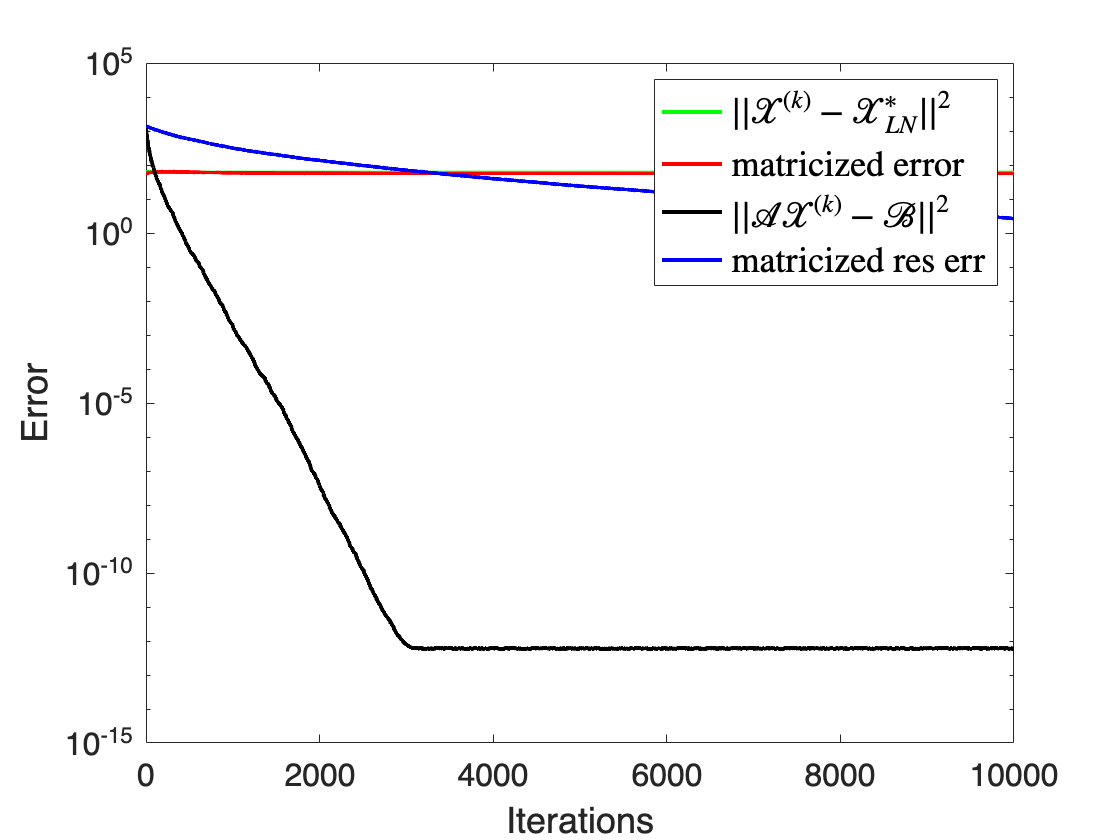

%plot errors vs iterations
figure(6);
semilogy(0:num_its,errs,'g-',0:num_its,mat_err,'r-',0:num_its,res_errs,'k-',0:num_its,mat_res_err,'b-','LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}^*||^2$','matricized error','$||\mathcal{A}\mathcal{X}^{(k)} - \mathcal{B}||^2$','matricized res err','Interpreter','latex','FontSize',18)
saveas(gca,'fig2_1.png')
hold off

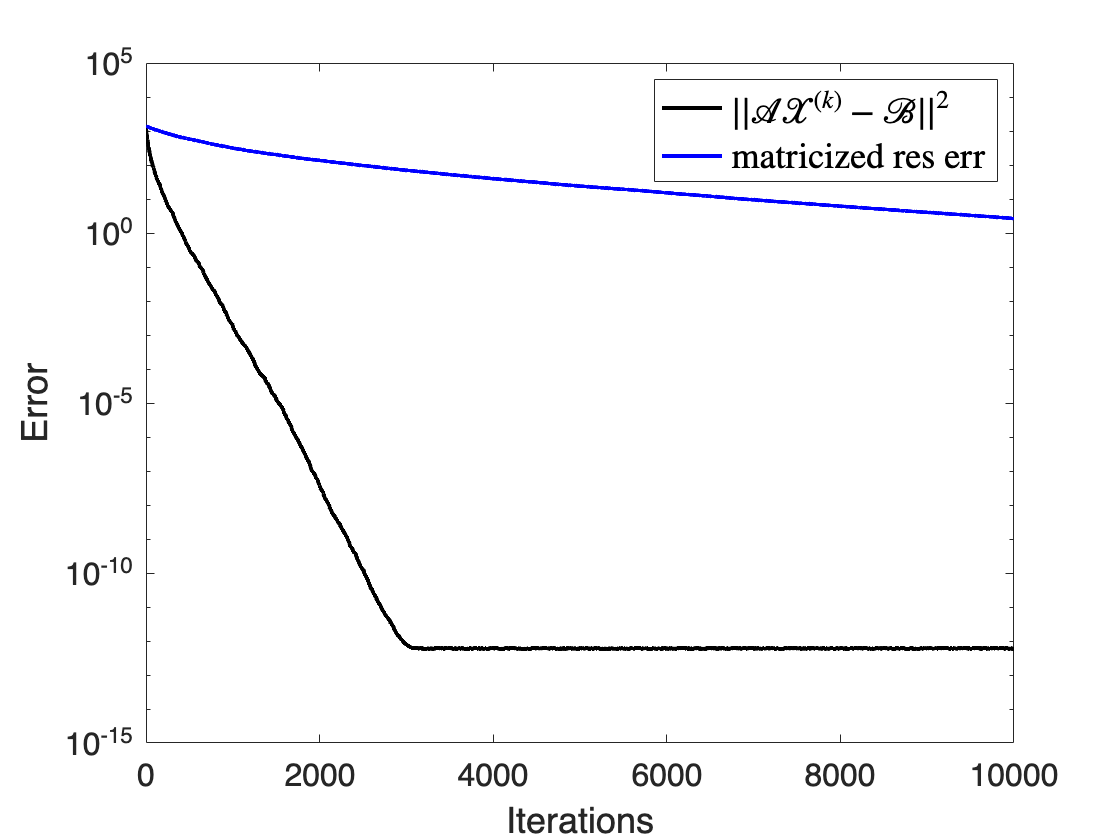

%plot errors vs iterations
figure(7);
semilogy(0:num_its,res_errs,'k-',0:num_its,mat_res_err,'b-','LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{A}\mathcal{X}^{(k)} - \mathcal{B}||^2$','matricized res err','Interpreter','latex','FontSize',18)
saveas(gca,'fig2_2.png')
hold off